clear all
% 100 logarthmically spaced points between 10^0 and 10^-20
h = logspace(-20,0,100);

x0 = pi/4;


% write the true value of the derviavtive of tan(x) evaluated at x0
TrueDeriv = sec(x0)*sec(x0)

TrueDeriv = 2.0000



% compute the numerical deriative of the given function using eq. (2.2) of assignment
% for all the values of h

dydx_approx = (tan(x0+h)-tan(x0))./h 

dydx_approx =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    4.8322    3.0348    3.1766    2.7930    2.2552    2.0458    2.0755    2.0483    2.0660    2.0320    2.0142    2.0181    2.0073    2.0071    2.0020    2.0024    2.0010    2.0008    2.0001    2.0002    2.0003    2.0001    2.0001    2.0001    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000



abserror=abs(TrueDeriv-dydx_approx)

abserror =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.8322    1.0348    1.1766    0.7930    0.2552    0.0458    0.0755    0.0483    0.0660    0.0320    0.0142    0.0181    0.0073    0.0071    0.0020    0.0024    0.0010    0.0008    0.0001    0.0002    0.0003    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000





% compute the truncation error using the expression you obtained in Question 2 part a)  
truncation_error = 2*sec(x0)*sec(x0)*tan(x0)*h/factorial(2)

truncation_error =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


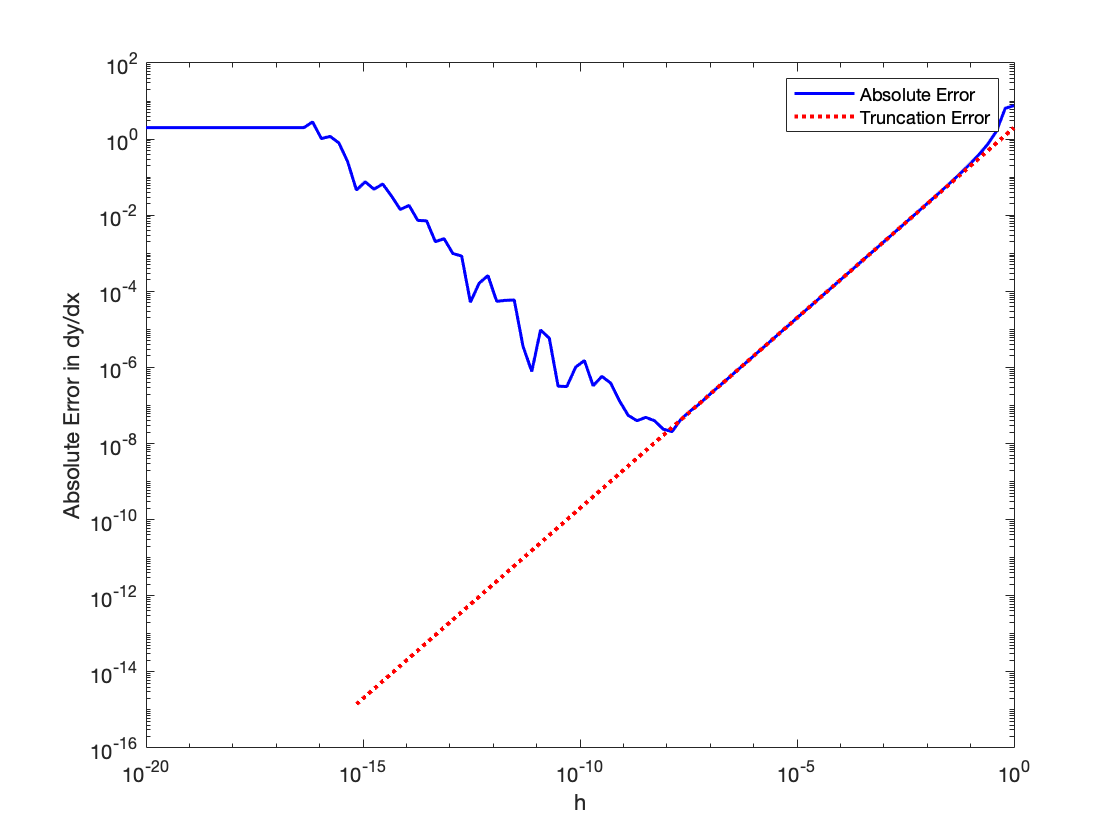



% compute the absolute error . It is already done for you.
% Absolute error is the difference between the True value of derivative and 
% estimated value of the derivative.
Absolute_error = abs(TrueDeriv - dydx_approx); 

clf
figure(1)
loglog(h,Absolute_error,'b','Linewidth',1.5)
hold on
figure(1)
loglog(h(25:100),truncation_error(25:100),'r:','Linewidth',2)

xlabel('h')
ylabel('Absolute Error in dy/dx')

legend('Absolute Error','Truncation Error')

%b i)
%Explanation

%For large values of h the error is smooth because it represents the
%trauncation error which is linear while for small values it is more
%erratic the round off error becomes dominant leading to a
%more erratic behavior of the total error

minabs=min(Absolute_error)

minabs = 2.0614e-08

h=sqrt((4*eps(min(Absolute_error)))/2*sec(x0)*sec(x0)*tan(x0))

h = 3.6380e-12